W_100_Heights = reshape(cell2mat(WHITE_100_Heights(:,3)),[],15);
W_100_H0_H6 = [WHITE{10,3}; W_100_Heights];
AS_wavelengths = [410, 440, 470, 510, 550, 583, 620, 670];
VEML_wavelengths = [650, 550, 450];

% plot(AS_wavelengths,W_100_H0_H6(1,1:8))
% hold on
% for i = 2:6
%     plot(AS_wavelengths,W_100_H0_H6(i,1:8))
% end
% hold off

% distances = flip([0, 4, 7.8, 11.5, 14.5, 17.5, 20.5]);

% plot(distances,W_100_H0_H6(:,3))
% hold on
% for i = 2:9
%     plot(distances,W_100_H0_H6(:,i))
% end
% legend("CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR")
% hold off

% d = 30:-5:5;
% DIST_2 = reshape(cell2mat(DIST(:,2)),[],15); % integrationtime = 160ms
% DIST_2(:,1);
% plot(d,DIST_2(:,1:9));
% legend("CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR");
% ax = gca;
% ax.ColorOrder = AS_Colours;
% plot(d,DIST_2(:,11:14));
% legend("Red", "Green", "Blue", "White")
% ax = gca;
% ax.ColorOrder = VEML_Colours;

% dist_plots("DistancevsOutputFigures",DISTas,DISTveml);
t = 4;
d = 30:-5:5;
DIST_AS = reshape(cell2mat(DISTas(:,t)),[],15);
DIST_AS_CLEAR = DIST_AS(:,9)

DIST_AS_CLEAR = 1.0e+04 *

    0.1090
    0.1537
    0.2365
    0.4158
    0.9584
    4.0905


DIST_AS_Normalised = DIST_AS(:,1:9)./DIST_AS(6,1:9);
DIST_AS_Normalised_CLEAR = DIST_AS_Normalised(:,9);

DIST_VEML = reshape(cell2mat(DISTveml(:,t)),[],15);
DIST_VEML_Normalised = DIST_VEML(:,11:14)./DIST_VEML(6,11:14)

DIST_VEML_Normalised =     0.0315    0.0312    0.0315    0.0322
    0.0445    0.0448    0.0451    0.0457
    0.0661    0.0663    0.0674    0.0677
    0.1095    0.1097    0.1136    0.1126
    0.2253    0.2209    0.2338    0.2323
    1.0000    1.0000    1.0000    1.0000


DIST_VEML_Normalised_CLEAR = DIST_VEML_Normalised(:,4);

model_AS_CLEAR = DIST_AS./AS_fittedmodel(d)

model_AS_CLEAR = 1.0e+05 *

    0.0088    0.1444    0.1374    0.1617    0.0330    0.0720    0.1820    0.0169    0.4340    0.0143    8.9206    8.9206    8.9206    8.9206    0.1275
    0.0084    0.1360    0.1276    0.1511    0.0288    0.0671    0.1590    0.0153    0.4018    0.0139    5.8551    5.8551    5.8551    5.8551    0.0837
    0.0083    0.1356    0.1296    0.1491    0.0285    0.0664    0.1675    0.0150    0.3985    0.0140    3.7735    3.7735    3.7735    3.7735    0.0539
    0.0086    0.1408    0.1430    0.1531    0.0290    0.0693    0.1954    0.0153    0.4138    0.0147    2.2288    2.2288    2.2288    2.2288    0.0318
    0.0085    0.1408    0.1390    0.1530    0.0287    0.0688    0.1887    0.0152    0.4087    0.0146    0.9549    0.9549    0.9549    0.9549    0.0136
    0.0085    0.1419    0.1327    0.1559    0.0280    0.0691    0.1713    0.0153    0.4091    0.0146    0.2240    0.2240    0.2240    0.2240    0.0032




y_clear = mean(model_AS_CLEAR)

y_clear = 1.0e+05 *

    0.0085    0.1399    0.1349    0.1540    0.0293    0.0688    0.1773    0.0155    0.4110    0.0144    3.6595    3.6595    3.6595    3.6595    0.0523


err_clear = std(model_AS_CLEAR)

err_clear = 1.0e+05 *

    0.0002    0.0034    0.0059    0.0044    0.0018    0.0020    0.0138    0.0007    0.0125    0.0004    3.2765    3.2765    3.2765    3.2765    0.0468


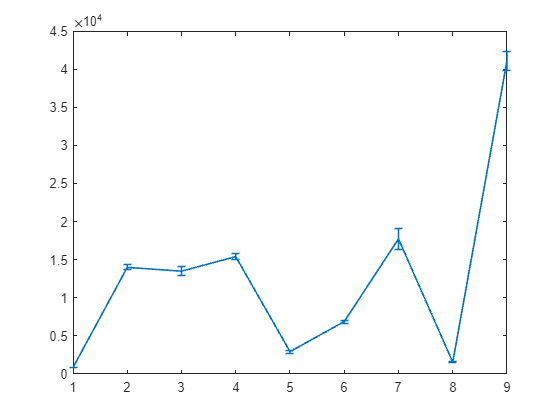


errorbar(1:9,y_clear(1:9),err_clear(1:9), 'LineWidth',1.2)

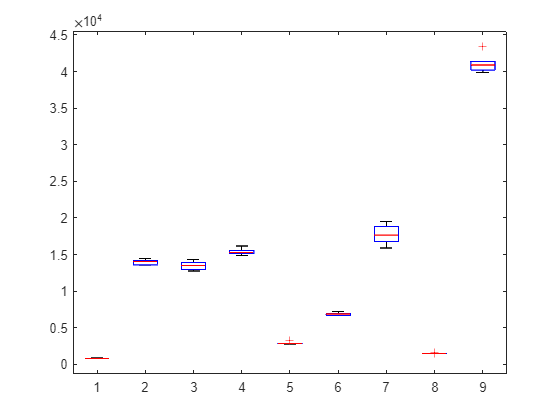

boxplot(model_AS_CLEAR(:,1:9));

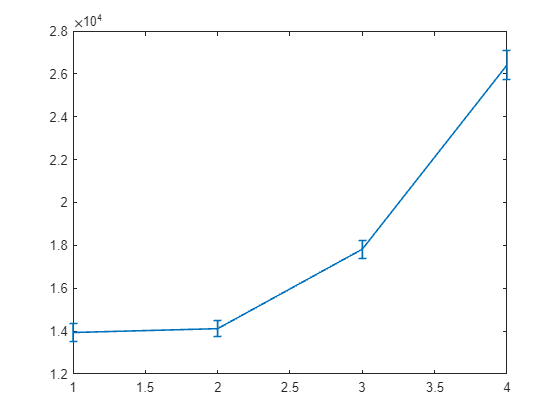

model_VEML_CLEAR = DIST_VEML./VEML_fittedmodel(d);

y_clear = mean(model_VEML_CLEAR(:,11:14));
err_clear = std(model_VEML_CLEAR(:,11:14));

errorbar(1:4,y_clear,err_clear,err_clear, 'LineWidth',1.2)

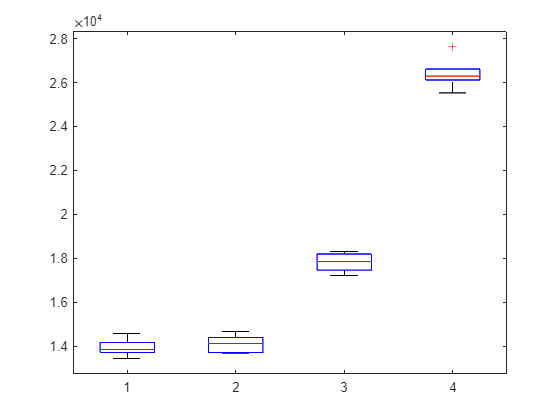

boxplot(model_VEML_CLEAR(:,11:14))

function dist_plots(direc,DISTas,DISTveml)
    AS_legend = ["CH1","CH2","CH3","CH4","CH5","CH6","CH7","CH8","CLEAR"];
    VEML_legend = ["RED", "GREEN", "BLUE", "CLEAR"];
    AS_Colours = [0.7 0 1; 0 0 1; 0 1 1; 0 1 0; 1 1 0; 1 0.6 0; 1 0 0; 0.7 0 0; 0 0 0];
    VEML_Colours = [1 0 0; 0 1 0; 0 0 1; 0 0 0];
    d = 30:-5:5;

    for t = 1:6
        DIST_AS = reshape(cell2mat(DISTas(:,t)),[],15);
        DIST_AS_Normalised = DIST_AS(:,1:9)./DIST_AS(6,1:9);
        
        DIST_VEML = reshape(cell2mat(DISTveml(:,t)),[],15);
        DIST_VEML_Normalised = DIST_VEML(:,11:14)./DIST_VEML(6,11:14);
        
        f = figure();
        plot(d,DIST_AS(:,1:9), 'LineWidth',1.2);
        
        ax = gca;
        ax.ColorOrder = AS_Colours;
        
        xlabel("Distance (cm)",'FontSize',14);
        ylabel("Counts",'FontSize',14)
        plot_title = sprintf("AS7341 Channel Responses vs. Distance");
        title(plot_title,'FontSize', 18)
        legend(AS_legend,'Location','northeast','NumColumns',2);
        set(gcf,'units','normalized','outerposition',[0 0 0.5 0.5]);
        
        filename = sprintf("%s/AS_%d_WHITE_distvcounts.jpg",direc,t);
        saveas(f,filename)
        close(f);
        
        
        f = figure();
        plot(d,DIST_AS_Normalised(:,1:9), 'LineWidth',1.2);
        
        ax = gca;
        ax.ColorOrder = AS_Colours;
        
        xlabel("Distance (cm)",'FontSize',14);
        ylabel("Counts",'FontSize',14)
        plot_title = sprintf("AS7341 Normalised Channel Responses vs. Distance");
        title(plot_title,'FontSize', 18)
        legend(AS_legend,'Location','northeast','NumColumns',2);
        set(gcf,'units','normalized','outerposition',[0 0 0.5 0.5]);
        
        filename = sprintf("%s/AS_Normalised_%d_WHITE_distvcounts.jpg",direc,t);
        saveas(f,filename)
        close(f);
        
        f = figure();
        plot(d,DIST_VEML(:,11:14), 'LineWidth',1.2);
        
        ax = gca;
        ax.ColorOrder = VEML_Colours;
        
        xlabel("Distance (cm)",'FontSize',14);
        ylabel("Counts",'FontSize',14)
        plot_title = sprintf("VEML6040 Channel Responses vs. Distance");
        title(plot_title,'FontSize', 18)
        legend(VEML_legend,'Location','northeast','NumColumns',2);
        set(gcf,'units','normalized','outerposition',[0 0 0.5 0.5]);
        
        filename = sprintf("%s/VEML_%d_WHITE_distvcounts.jpg",direc,t);
        saveas(f,filename)
        close(f);
        
        
        f = figure();
        plot(d,DIST_VEML_Normalised(:,:), 'LineWidth',1.2);
        
        ax = gca;
        ax.ColorOrder = VEML_Colours;
        
        xlabel("Distance (cm)",'FontSize',14);
        ylabel("Counts",'FontSize',14)
        plot_title = sprintf("VEML6040 Normalised Channel Responses vs. Distance");
        title(plot_title,'FontSize', 18)
        legend(VEML_legend,'Location','northeast','NumColumns',2);
        set(gcf,'units','normalized','outerposition',[0 0 0.5 0.5]);
        
        filename = sprintf("%s/VEML_Normalised_%d_WHITE_distvcounts.jpg",direc,t);
        saveas(f,filename)
        close(f);
    end
end
function COLOUR_Scaled = scale(COLOUR)
    factors = [4, 2, 1, 0.5, 0.25, 0.125];
    COLOUR_Scaled = cell(6,6);
    for j = 1:10
        for i = 1:6
            COLOUR_Scaled{j,i} = COLOUR{j, i}.*factors(i);
        end
    end
end